addpath('KDC_project\mr\')

% q = {x_m(t),y_m(t),q_l(t),q_r(t),q_1(t),q2(t)}
% Define initial and goal states
q_start = [1.0,1.0,2.0,1.0,pi/4,pi/6];
q_dot_start = [0.0,0.0,0.0,0.0,0.0,0.0];
q_dot_dot_start = [0.0,0.0,0.0,0.0,0.0,0.0];

q_goal = [1.0,5.0,2.0,5.0,pi/2,pi/2];
q_dot_goal = [0.0,0.0,0.0,0.0,0.0,0.0];
q_dot_dot_goal = [0.0,0.0,0.0,0.0,0.0,0.0];

% q_goal = [1.0,5.0,2.0,5.0,pi/2,pi/2];
% q_dot_goal = [2.0,3.0,4.0,-1.0,pi/20,pi/20];
% q_dot_dot_goal = [1,1,1,1,1,1];

% Compute optimal trajectory time

[tf_final,energy_vals] = optimal_time(q_start, q_dot_start, q_dot_dot_start, q_goal, q_dot_goal, q_dot_dot_goal)

   3.5540e+03

   2.8572e+03

   2.5924e+03

   3.2963e+03

   6.3558e+03

   1.5948e+04



tf_final = 0.5000

energy_vals = 	1.0e+04 *

    0.4452    0.3554    0.2857    0.2592    0.3296    0.6356    1.5948


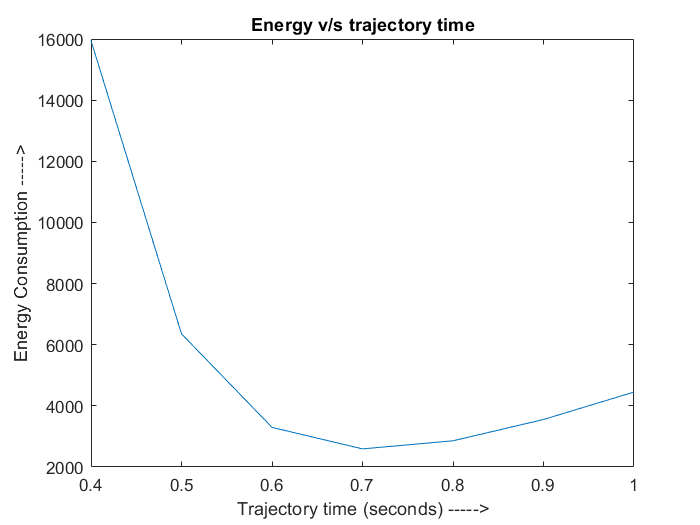


x = 2.0:-0.1:0.4;
plot(x, energy_vals)
title('Energy v/s Total Time')
xlabel("Total Time (seconds) ----->")
ylabel("Energy Consumption Index ----->")

function [tf_final,energy_vals] = optimal_time(q_start, q_dot_start, q_dot_dot_start, q_goal, q_dot_goal, q_dot_dot_goal)
    energy = 10000000;
    tf = 2.0;
    
    [vars_list, tau_left_t, tau_r_t, tau_1_t, tau_2_t] = get_torque_at_t();
    
    [q_t,q_dot_t,q_dot_dot_t] = get_state_at_t(q_start, q_dot_start, q_dot_dot_start, q_goal, q_dot_goal, q_dot_dot_goal,tf);
    energy_curr = get_energy(vars_list, tau_left_t, tau_r_t, tau_1_t, tau_2_t, q_t, q_dot_t, q_dot_dot_t, tf);
    tf_final = 2000;
    step_size = 0.1;
    
    
    energy_vals = [energy_curr];
    while tf>0.5
        tf_final = tf;
        energy = energy_curr;  
        tf = tf - step_size;
        [q_t,q_dot_t,q_dot_dot_t] = get_state_at_t(q_start, q_dot_start, q_dot_dot_start, q_goal, q_dot_goal, q_dot_dot_goal,tf);
        
        energy_curr = get_energy(vars_list, tau_left_t, tau_r_t, tau_1_t, tau_2_t, q_t, q_dot_t, q_dot_dot_t, tf);
        disp(energy_curr)
        energy_vals(end+1) = energy_curr;
    end
end

function [s_t, s_dot_t, s_dot_dot_t] = get_polynomials(tf)
    syms t;
    s_t = QuinticTimeScaling(tf,t);
    s_dot_t = diff(s_t,t);
    s_dot_dot_t = diff(s_dot_t,t);
end

function [q_t,q_dot_t,q_dot_dot_t] = get_state_at_t(q_start, q_dot_start, q_dot_dot_start, q_goal, q_dot_goal, q_dot_dot_goal,tf)
    [s_t,s_dot_t,s_dot_dot_t] = get_polynomials(tf);     
    
    % Modify below lines if starting and goal velocities and accelerations
    % are non-zero. These equations consider them to be zeros.
    
    q_t = q_start + ((q_goal-q_start)*s_t);
    q_dot_t = (q_goal-q_start)*s_dot_t;
    q_dot_dot_t = (q_goal-q_start)*s_dot_dot_t;
end

function [q, q_dot, q_dot_dot] = get_joint_state(q_t,q_dot_t,q_dot_dot_t, t)
    q = double(subs(q_t,t));
    q_dot = double(subs(q_dot_t,t));
    q_dot_dot = double(subs(q_dot_dot_t,t));
end


function energy = get_energy(var_lists, tau_left_t, tau_r_t, tau_1_t, tau_2_t, q_t,q_dot_t,q_dot_dot_t, t)
    energy = 0;
    for curr_t = 0:0.01:t
        [q,q_dot,q_dot_dot] = get_joint_state(q_t,q_dot_t,q_dot_dot_t,curr_t);
        [tau_left, tau_r, tau_1, tau_2] = get_torque(var_lists, tau_left_t, tau_r_t, tau_1_t, tau_2_t, q, q_dot, q_dot_dot);
        energy = energy + tau_left^2 + tau_r^2 + tau_1^2 + tau_2^2;
    end
end

function [vars_list, tau_left_t, tau_r_t, tau_1_t, tau_2_t] = get_torque_at_t()
    L = 0.25;            % half length of body
    L_cmx1 = 0.167;   % length between joint 1 and cm of link 1
    L_cmx2 = 0.246;       % length between joint 2 and cm of link 2
    L_0 = 0.325;          % height of joint 1
    L_1 = 0.2;          % length of link 1 
    L_2 = 0.3;          % length of link 2
    r = 0.075;             % Radius of wheel
    I_m = 0.7; Izz_1 = 0.023; Iyy_1 = 0.0221; Izz_2 = 0.046; Iyy_2 = 0.045; Iyy_w = 0.0015; Izz_w = 0.003;
    g = 10.0;
    m_w = 0.9; m_m = 19.0; m_1 = 3.2; m_2 = 3.4;

    syms x_m(t)       % body x
    syms y_m(t)       % body y
    syms q_1(t)  % theta of joint 1
    syms q_2(t)  % theta of joint 2 
    syms q_r(t) q_l(t)

    q_m = (r / 2 * L) * (q_r(t) - q_l(t));
    x_cm_r = x_m(t) + L * sin(q_m); %%
    y_cm_r = y_m(t) - L * cos(q_m); %%
    x_cm_l = x_m(t) - L * sin(q_m); %%
    y_cm_l = y_m(t) + L * cos(q_m); %% 
    
    x_cm_m = x_m(t); %%
    y_cm_m = y_m(t); %%
    
    %%x_cm_1 = x_m(t) + L_cmx1*cos(q_m); %%
    x_cm_1 = x_m(t) + (L_cmx1*cos(q_1(t))) * cos(q_m);
    %%y_cm_1 = y_m(t) + L_cmx1*sin(q_m); %%
    y_cm_1 = y_m(t) + (L_cmx1*sin(q_1(t))) * sin(q_m); %%
    z_cm_1 = L_0 + L_cmx1*sin(q_1(t)); %%
    
    %%x_cm_2 = x_m(t) + L_1*cos(q_m) + L_cmx2*cos(q_m); %%
    x_cm_2 = x_m(t) + (L_1*cos(q_1(t))) * cos(q_m) + (L_cmx2 * cos(q_1(t)+q_2(t))) * cos(q_m); %%
    %%y_cm_2 = y_m(t) + L_1*sin(q_m) + L_cmx2*sin(q_m); %%
    y_cm_2 = y_m(t) + (L_1*cos(q_1(t))) * sin(q_m) + (L_cmx2 * cos(q_1(t)+q_2(t))) * sin(q_m); 
    
    z_cm_2 = L_0 + L_1*sin(q_1(t)) + L_cmx2*sin(q_1(t)+q_2(t)); 

    %%% 1st Diff
    x_cm_r_dot = diff(x_cm_r,t);
    y_cm_r_dot = diff(y_cm_r,t);
    
    x_cm_l_dot = diff(x_cm_l,t);
    y_cm_l_dot = diff(y_cm_l,t);
    
    x_cm_m_dot = diff(x_cm_m,t);
    y_cm_m_dot = diff(y_cm_m,t);
    
    x_cm_1_dot = diff(x_cm_1,t);
    y_cm_1_dot = diff(y_cm_1,t);
    z_cm_1_dot = diff(z_cm_1,t);
    
    x_cm_2_dot = diff(x_cm_2,t);
    y_cm_2_dot = diff(y_cm_2,t);
    z_cm_2_dot = diff(z_cm_2,t);
    
    q_m_dot = diff(q_m,t);
    
    x_m_dot = diff(x_m(t),t);
    y_m_dot = diff(y_m(t),t);
    q_l_dot = diff(q_l(t),t);
    q_r_dot = diff(q_r(t),t);
    q_1_dot = diff(q_1(t),t);
    q_2_dot = diff(q_2(t),t);
    
    x_m_ddot = diff(x_m_dot,t);
    y_m_ddot = diff(y_m_dot,t);
    q_l_ddot = diff(q_l_dot,t);
    q_r_ddot = diff(q_r_dot,t);
    q_1_ddot = diff(q_1_dot,t);
    q_2_ddot = diff(q_2_dot,t);
    
    vars_list = [x_m(t),y_m(t),q_l(t),q_r(t),q_1(t),q_2(t),x_m_dot,y_m_dot,q_l_dot,q_r_dot,q_1_dot,q_2_dot,x_m_ddot,y_m_ddot,q_l_ddot,q_r_ddot,q_1_ddot,q_2_ddot];
    

    %%%%% Energy Equations
    K_R = 0.5 * m_w * (x_cm_r_dot^2 + y_cm_r_dot^2) + 0.5 * Iyy_w * q_m_dot^2 + 0.5 * Izz_w * q_r_dot^2;
    K_L = 0.5 * m_w * (x_cm_l_dot^2 + y_cm_l_dot^2) + 0.5 * Iyy_w * q_m_dot^2 + 0.5 * Izz_w * q_l_dot^2;  
    
    K_M = 0.5 * m_m * (x_cm_m_dot^2 + y_cm_m_dot^2) + (0.5 * I_m * q_m_dot^2);
    K_1 = 0.5 * m_1 * (x_cm_1_dot^2 + y_cm_1_dot^2 + z_cm_1_dot^2) + (0.5 * Izz_1 * (q_m_dot)^2) + (0.5 * Iyy_1 * (q_1_dot)^2);
    K_2 = 0.5 * m_2 * (x_cm_2_dot^2 + y_cm_2_dot^2 + z_cm_2_dot^2) + (0.5 * Izz_2 * (q_m_dot)^2) + (0.5 * Iyy_2 * (q_1_dot + q_2_dot)^2);
    
    P_R = 0;
    P_L = 0;
    P_M = 0;
    P_1 = -m_1 * g * (L_0+L_cmx1 * sin(q_1));  % Doubt: Should L_0 be from the center of the body? or Floor
    P_2 = -m_2 * g * (L_0 + L_1 * sin(q_1) + L_cmx2 * sin(q_1 + q_2));
    
    %%%%% Lagrangian Equation 
    Lagran = (K_R - P_R) + (K_L - P_L) + (K_1 - P_1) + (K_2 - P_2) ;
    
    tau_r_t = diff(diff(Lagran,q_r_dot), t) - diff(Lagran,q_r(t));
    tau_left_t = diff(diff(Lagran,q_l_dot), t) - diff(Lagran,q_l(t));
    tau_1_t = diff(diff(Lagran,q_1_dot),t) - diff(Lagran,q_1(t));
    tau_2_t = diff(diff(Lagran,q_2_dot),t) - diff(Lagran,q_2(t));

end

function [tau_left, tau_r, tau_1, tau_2] = get_torque(var_list, tau_left_t, tau_r_t, tau_1_t, tau_2_t, q, q_dot, q_dot_dot)
    q_state =  q;
    q_state = cat(2,q_state,q_dot);
    q_state = cat(2,q_state,q_dot_dot);
    
    tau_left = double(subs(tau_left_t,var_list, q_state));
    tau_r = double(subs(tau_r_t,var_list, q_state));
    tau_1 = double(subs(tau_1_t,var_list, q_state));
    tau_2 = double(subs(tau_2_t,var_list, q_state));
end